# HW7

*Steven Henderson*

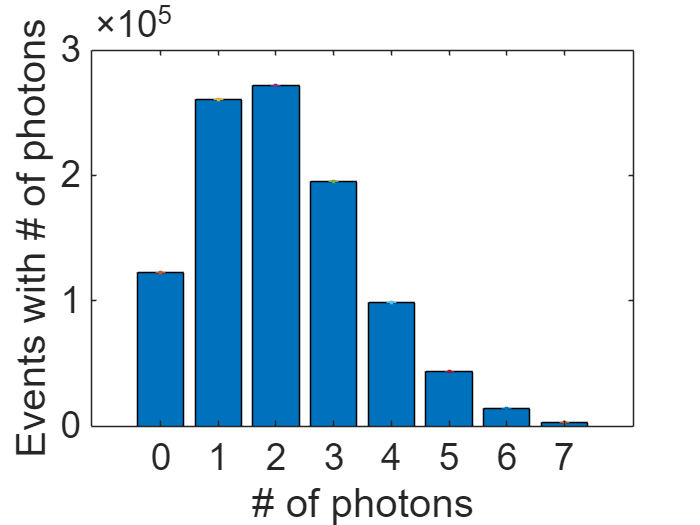

c_high = readmatrix('PhotonCountingHigh.xlsx')  ;
c_low = readmatrix('PhotonCountingLow.xlsx') ;
figure % this makes a Figure object
bar(c_low(:, 1), c_low(:, 2)) %
set(gca,'fontsize',22)
hold on ;
errorbar(c_low(:, 1), c_low(:, 2), sqrt(length(c_low(:, 1))),'.')
hold off;
xlabel('# of photons')
ylabel('Events with # of photons')

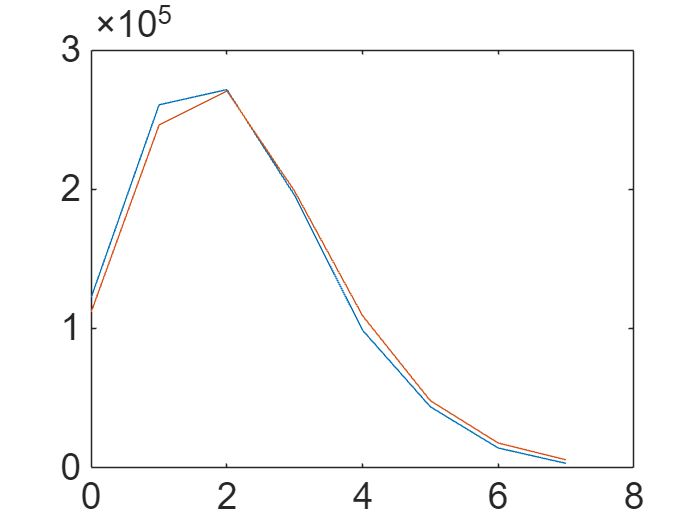

y = poisspdf(c_low(:, 1), 2.2) ;
figure % this makes a Figure object
plot(c_low(:, 1), c_low(:, 2)) %
set(gca,'fontsize',22)
hold on ;
plot(c_low(:, 1), y*sum(c_low(:, 2)))
hold off;